# Sociophysics Project

## The True Number of Heterosexual Partners 

For a sanity check, we want to compute the ratio for the average number of heterosexual partners for males versus females. Let $S_{\mu
}$ and $S_{\nu}$ be the average number of sexual partners for the population of heterosexual males and females, respectively. Based on a 2016 study by J. M. Bailey et al. 93% of males and 87% of females identify as heterosexual. Moreover according to the UN population census data, the ratio of the population of males to females is $P_R=\frac{P_{\mu}}{P_{\nu}}=1.01016$. 

Now, assuming uniform percentage in the number of heterosexual males and females, we should predict that the ratio of number of sexual partners is $S_R=\frac{P_{\mu}}{P_{\mu}}\cdot\frac{0.93}{0.87}\approx1.0798262069$. 

This number is obtained by a graph theoretic approach, as the number of nodes on the left and right sides represent the individual males and female, respectively. The number of edges represents the number of sexual interactions. The degree represents the number of sexual partners. Let this number using a simulation.  

The maximum total number of sexual partners is $P_{\mu}\cdot P_{\nu}$. According to census data by the CDC, (C. D. Fryar, et al.) 2.1% of the population have never had sex in their lifetime. Therefore, the minimum number of sexual interactions is $P_{\mu}\cdot 0.979.$ Let us set an upper bound for the total number of sexual interations to be $10\cdot P_{\mu}$

According to world census data, the current population is $8.1\times 10^9$. Thus, $P_{\mu}=4042987695$ and $P_{\nu}=4002323752$. Unfortunately, we can only generate a maximum number of $2^{48}$ sexual interactions. First, let us generate a small population of males and females:

Female_Pop = 20

Female_Pop = 20

Male_Pop = 20

Male_Pop = 20

Now, we can create graph with this number of nodes, and generate a psuedo-random number of sexual interactions per node. Let the numbers from 1 to 4042987695 be the male population and the numbers 4042987696 to 8045311447 be the female population.

Male_Nodes = 1:Male_Pop;
Female_Nodes = (Male_Pop+1):(Male_Pop+Female_Pop);

Now, we assign a random probability for each node for a connection to occur.

% Assign random probabilities of interaction to each node
Male_Probabilities = rand(1, Male_Pop)*0.1;
Female_Probabilities = rand(1, Female_Pop)*0.1;

From here, we generate a graph, where the connections are based on the assigned interaction probabilities 

edges = [];
for m = Male_Nodes
    for f = Female_Nodes 
        connectionProbability = Male_Probabilities(m) * Female_Probabilities(f - Male_Pop); % Interaction probability for the specific pair
        if rand() < connectionProbability
            edges = [edges; m f];
        end
    end
end

With this, we create a graph, and plot it, and denote the male and females nodes with a blue and red node, respectively

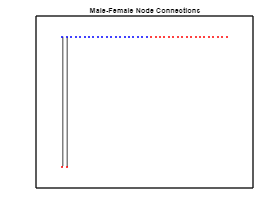

% Create graph
G = graph(edges(:,1), edges(:,2));

% Plot graph
figure;
p = plot(G, 'EdgeColor', 'k');
title('Male-Female Node Connections');

% Set male nodes to blue and female nodes to red
p.NodeCData = [ones(Male_Pop,1)*1; ones(Female_Pop,1)*2]; % 1 for male (blue), 2 for female (red)
p.MarkerSize = 2;
colormap([0 0 1; 1 0 0]); % blue for male, red for female
% Remove node numbering
p.NodeLabel = {};

Now, we can calculate the number of sexual partners by calculating the degree of each node.

% Calculate the degree of each node
nodeDegrees = degree(G);
% Calculate the degree of each male and female nodes
Sex_Male = nodeDegrees(Male_Nodes)

Sex_Male =      0
     0
     0
     0
     1
     0
     0
     0
     0
     1


Sex_Female = nodeDegrees(Female_Nodes)

Sex_Female =      0
     0
     0
     0
     1
     0
     0
     0
     0
     0


Finally, we can calculate the average number of sexual interaction for males versus females by summing the degrees.

% Sum the degree of male and female nodes
Sex_Count_Male = sum(Sex_Male)

Sex_Count_Male = 2

Sex_Count_Female = sum(Sex_Female)

Sex_Count_Female = 2

%Calculating the average
Average_Sex_Male = Sex_Count_Male/Male_Pop

Average_Sex_Male = 0.1000

Average_Sex_Female = Sex_Count_Female/Female_Pop

Average_Sex_Female = 0.1000

We can compare by taking the ratio.

Average_Sex_Female/Average_Sex_Male

ans = 1

## Consider Homosexual and Bisexual Males and Females

We perform a similar analysis as above, however consider both homosexual and bisexual males and females. The rules are now modified such that:

1.) Heterosexual males/females can connect with their heterosexual counterparts.

2.) Homosexual males/females can connect with other homosexual/bisexual males/females.

3.) Bisexual males/females can connect with anyone except for heterosexual males/females.

% Number of male, female, bi_male, and bi_female nodes
HeteroMalePop = 20;
HeteroFemalePop = 20;
HomoMalePop = 10;
HomoFemalePop = 10;
BiMalePop = 8;
BiFemalePop = 8;
MalePopTotal = HeteroMalePop+HomoMalePop+BiMalePop;
FemalePopTotal = HeteroFemalePop+HomoFemalePop+BiFemalePop;

% Create nodes
HeteroMaleNodes = 1:HeteroMalePop;
HeteroFemaleNodes = (HeteroMalePop+1):(HeteroMalePop+HeteroFemalePop);
HomoMaleNodes = (HeteroMalePop+HeteroFemalePop+1):(HeteroMalePop+HeteroFemalePop+HomoMalePop);
HomoFemaleNodes = (HeteroMalePop+HeteroFemalePop+HomoMalePop+1):(HeteroMalePop+HeteroFemalePop+HomoMalePop+HomoFemalePop);
BiMaleNodes = (HeteroMalePop+HeteroFemalePop+HomoMalePop+HomoFemalePop+1):(HeteroMalePop+HeteroFemalePop+HomoMalePop+HomoFemalePop+BiMalePop);
BiFemaleNodes = (HeteroMalePop+HeteroFemalePop+HomoMalePop+HomoFemalePop+BiMalePop+1):(HeteroMalePop+HeteroFemalePop+HomoMalePop+HomoFemalePop+BiMalePop+BiFemalePop);

PopNodes = [HeteroMaleNodes, HeteroFemaleNodes, HomoMaleNodes, HomoFemaleNodes, BiMaleNodes, BiFemaleNodes];

% Assign random probabilities of interaction to each node
nodeProbabilities  = normrnd(0.05,0.5,length(PopNodes));

% Create edges with random connections based on interaction probabilities
edges = [];
for i = 1:length(PopNodes)
    for j = i+1:length(PopNodes)
        % Check if the pair can connect based on the given conditions
        canConnect = ((ismember(i, HeteroMaleNodes) && ismember(j, HeteroFemaleNodes)) || ...
                      (ismember(i, HeteroFemaleNodes) && ismember(j, HeteroMaleNodes)) || ...
                      (ismember(i, HomoMaleNodes) && (ismember(j, HomoMaleNodes) || ismember(j, BiMaleNodes))) || ...
                      (ismember(i, HomoFemaleNodes) && (ismember(j, HomoFemaleNodes) || ismember(j, BiFemaleNodes))) || ...
                      (ismember(i, BiMaleNodes) && (ismember(j, HomoMaleNodes) || ismember(j, HeteroFemaleNodes) || ismember(j, BiFemaleNodes))) || ...
                      (ismember(i, BiFemaleNodes) && (ismember(j, HomoFemaleNodes) || ismember(j, HeteroMaleNodes) || ismember(j, BiMaleNodes))) || ...
                      (ismember(i, HeteroFemaleNodes) && ismember(j, BiMaleNodes)) || ...
                      (ismember(i, HeteroMaleNodes) && ismember(j, BiFemaleNodes)));
        if canConnect
            connectionProbability = nodeProbabilities(i) * nodeProbabilities(j); % Interaction probability for the specific pair
            if rand() < connectionProbability
                edges = [edges; PopNodes(i) PopNodes(j)];
            end
        end
    end
end

% Create graph
G1 = graph(edges(:,1), edges(:,2));

% Plot graph
h=figure;
p = plot(G1, 'EdgeColor', 'k', 'HandleVisibility', 'off');
set(h,'Units','Inches');
pos = get(h,'Position');
set(h,'PaperPositionMode','Auto','PaperUnits','Inches','PaperSize',[pos(3), pos(4)])
print(h,'filename','-dpdf','-r0')

% Set node colors: blue for hetero_male, red for hetero_female, green for homo_male, yellow for homo_female, cyan for bi_male, magenta for bi_female
nodeColors = [ones(HeteroMalePop,1)*1; ones(HeteroFemalePop,1)*2; ones(HomoMalePop,1)*3; ones(HomoFemalePop,1)*4; ones(BiMalePop,1)*5; ones(BiFemalePop,1)*6];
p.NodeCData = nodeColors;
p.MarkerSize = 5;
colormap([0 0 1; 1 0 0; 0 1 0; 1 1 0; 0 1 1; 1 0 1]);

% Remove node numbering
p.NodeLabel = {};

% Calculate degrees
nodeDegrees = degree(G1);

% Sum degrees for male and female nodes
maleNodes = [HeteroMaleNodes, HomoMaleNodes, BiMaleNodes];
femaleNodes = [HeteroFemaleNodes, HomoFemaleNodes, BiFemaleNodes];

sumMaleDegrees = sum(nodeDegrees(maleNodes));
sumFemaleDegrees = sum(nodeDegrees(femaleNodes));

% Display the results
disp(['Sum of degrees for male nodes: ', num2str(sumMaleDegrees)]);

Sum of degrees for male nodes: 118


disp(['Sum of degrees for female nodes: ', num2str(sumFemaleDegrees)]);

Sum of degrees for female nodes: 128


disp(['Average number of sexual interactions per male: ', num2str(sumMaleDegrees/MalePopTotal)]);

Average number of sexual interactions per male: 3.1053


disp(['Average number of sexual interactions per female: ', num2str(sumFemaleDegrees/FemalePopTotal)]);

Average number of sexual interactions per female: 3.3684



% Create the legend without legend label data
hold on;
scatter(nan, nan, 100, [0 0 1], 'filled', 'DisplayName', 'Heterosexual Males');
scatter(nan, nan, 100, [1 0 0], 'filled', 'DisplayName', 'Heterosexual Females');
scatter(nan, nan, 100, [0 1 0], 'filled', 'DisplayName', 'Homosexual Males');
scatter(nan, nan, 100, [1 1 0], 'filled', 'DisplayName', 'Homosexual Females');
scatter(nan, nan, 100, [0 1 1], 'filled', 'DisplayName', 'Bisexual Males');
scatter(nan, nan, 100, [1 0 1], 'filled', 'DisplayName', 'Bisexual Females');

legendObj = legend('show', 'Interpreter', 'latex');
%legendObj = legend('show', 'Location', 'southoutside', 'Interpreter', 'latex');
legendObj.NumColumns = 3; % Set the number of columns for the legend
legendPos = get(legendObj, 'Position');
legendPos(1) = 0.52 - legendPos(3) / 2; % Center horizontally
legendPos(2) = 0.01 % Place it just outside the bottom of the graph

legendPos =     0.1050    0.0100    0.8299    0.0793


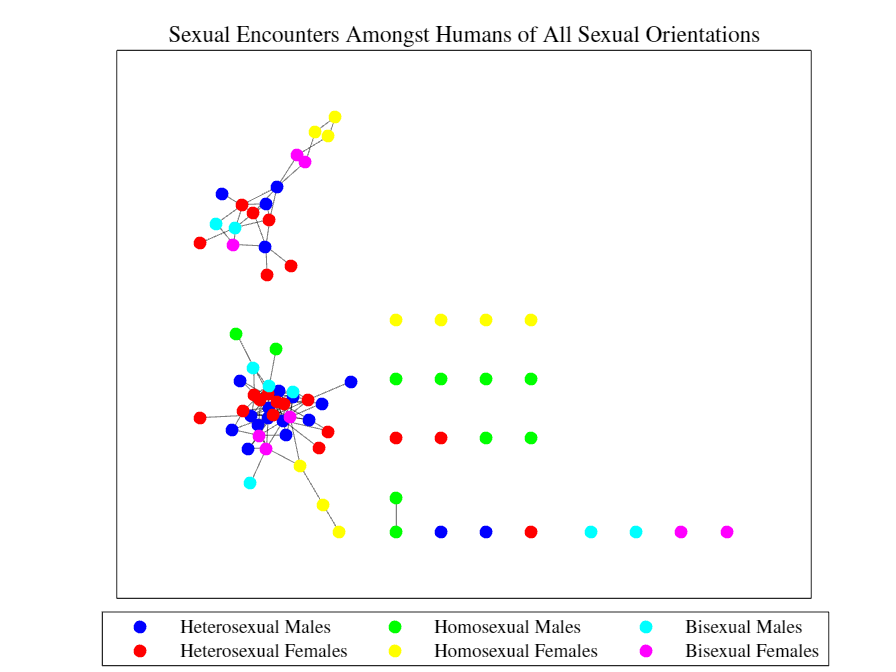

set(legendObj, 'Position', legendPos);

% Set the axis labels with LaTeX interpreter
title('Sexual Encounters Amongst Humans of All Sexual Orientations', 'Interpreter', 'latex');

% Save the figure
saveas(gcf, 'node_connections_figure.pdf');

    hold off;

## Exaggeration and Reservation

The most trivial way to explain this discrepancy is to assume that the males exaggerate the number of sexual encounters and females reserve  the number of sexual encounters due to societal perception. In an attempt to reproduce the results what we can do is add "liars" to the sample space. To do so, we can simply use a pseudo-random number generator and add/subtract a "correction" term to the male/female 